# ***Battery State of Charge Estimation using Extended Kalman Filter***

## Ghani Amri Rabbani, Ary Syahriar, Dwi Astharini, Haris Al-Qodri Maarif, Ahmad Husin Lubis, Danny Mokhammad Gandana

**Instructions for Downloading and Running the Script**

- Download raw datasets of Samsung battery from Mendeley Data page [https://data.mendeley.com/datasets/9xyvy2njj3/1](https://data.mendeley.com/datasets/9xyvy2njj3/1) 

- After downloading all the files including this one, unzip the file to a folder, do not modify the folder structure.

- Navigate to the folder with "DSP_EKF_SOC_Estimation.mlx" and "DSP_EKF_SOC_Graph.mlx".

- Open both files and run "DSP_EKF_SOC_Graph.mlx".

- The matlab script should run properly without any modification. If required, follow the comprehensive step-by-step in README file.

The main goal of this script is to provide a study of battery State of Charge (SOC) estimation using the Extended Kalman Filter (EKF) reinforced with digital signal processing (DSP) technique. The following script analyzes the battery's SOC and terminal voltage (Vt) during a driving cycle using a 2nd Order R-RC Equivalent Circuit Model considering the effects of battery surface temperature.

Each file in folder "Prepared Dataset" named in abbreviation of U.S. EPA driving cycle in order: HWFET, UDDS, and US06 which contain specific operating temperatures.

Run each driving cycle at the same operating ambient temperature to get a different results as shown in the paper. 

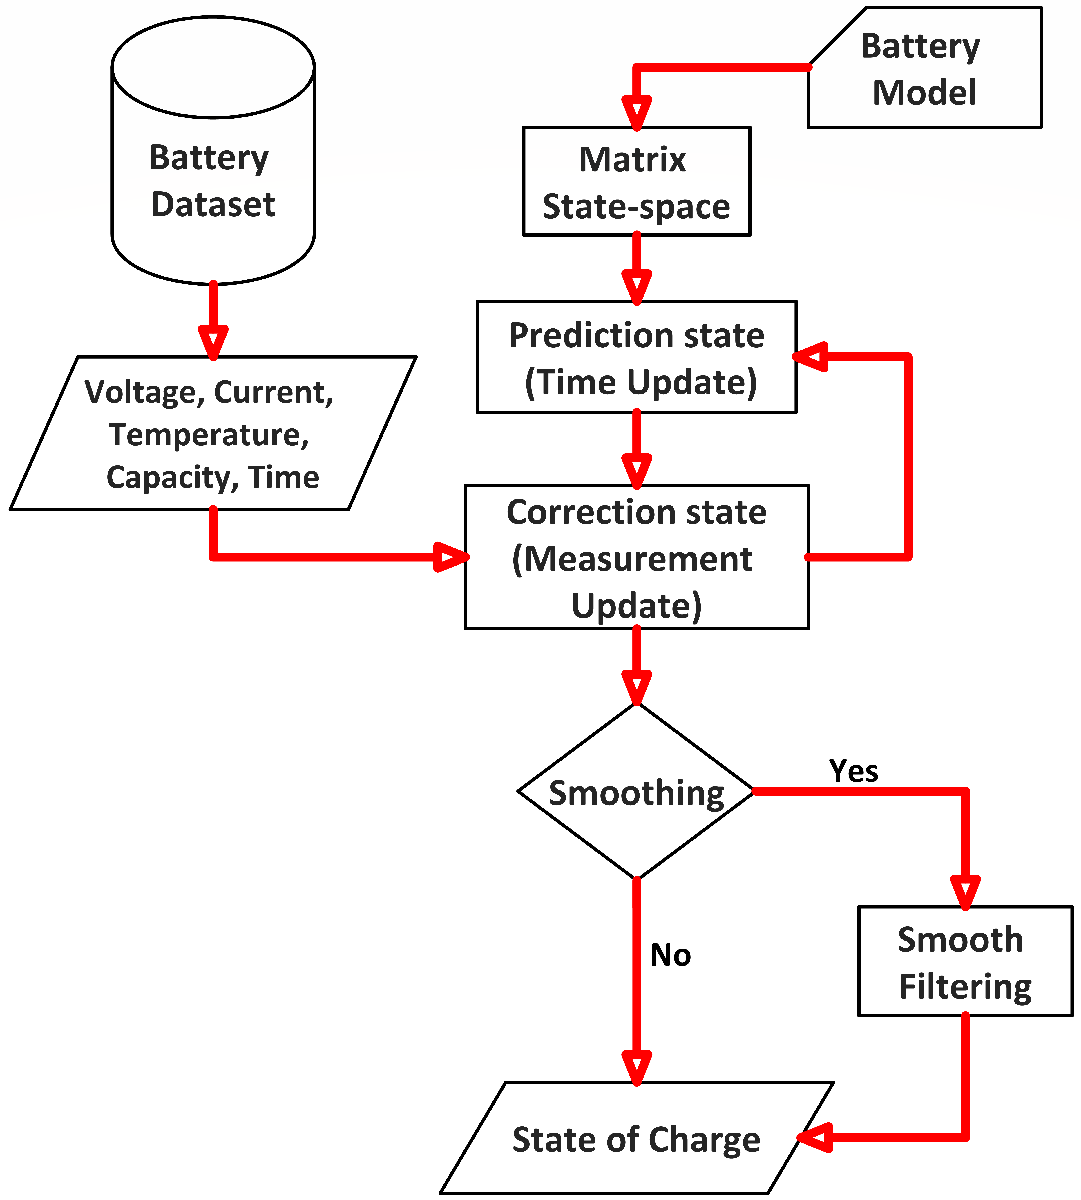

clc; clear; close all;

### Load Experimental Data

First, load the battery time, voltage, current, and temperature data of a driving cycle experiment. This will serve as an input into the EKF_SOC_Estimation function. Since the real SOC cannot be directly measured for comparison against the EKF estimated SOC, it is calculated using coloumb counting.

The battery manufacturer's nominal capacity can be used to calculate capacity. The nominal capacity used here should be the same as the variable $Cn$ in the EKF_SOC_Estimation function

load 'Samsung INR21700_PreparedDataset\Samsung_ResampleData'

% Uncomment this lines to select HWFET driving cycle
%LiIon.RecordingTime            = chop.B10_time_HWFET;
%LiIon.Measured_Voltage         = chop.B10_volt_HWFET;
%LiIon.Measured_Current         = chop.B10_curr_HWFET;
%LiIon.Measured_Temperature     = chop.B10_temp_HWFET;

% Uncomment this lines to select UDDS driving cycle
%LiIon.RecordingTime            = chop.B25_time_UDDS;
%LiIon.Measured_Voltage         = chop.B25_volt_UDDS;
%LiIon.Measured_Current         = chop.B25_curr_UDDS;
%LiIon.Measured_Temperature     = chop.B25_temp_UDDS;

% Uncomment this lines to select US06 driving cycle
LiIon.RecordingTime            = chop.B0_time_US06;
LiIon.Measured_Voltage         = chop.B0_volt_US06;
LiIon.Measured_Current         = chop.B0_curr_US06;
LiIon.Measured_Temperature     = chop.B0_temp_US06;

% Uncomment this lines for specified the driving cycle
nominalCap                     = 3; % Battery capacity in Ampere-hour (Ah) taken from data.
%LiIon.Measured_SOC             = ((nominalCap + chop.B10_Ah_HWFET).*100)./nominalCap;  % Calculate the SOC using Coloumb Counting for comparison
%LiIon.Measured_SOC             = ((nominalCap + chop.B25_Ah_UDDS).*100)./nominalCap;
LiIon.Measured_SOC             = ((nominalCap + chop.B0_Ah_US06).*100)./nominalCap;

Depending on the data size, resampling may be needed to save computational time. In the following code lines, the data was resampled from 6 Hz to 1 Hz. The user may comment this part if desired.


%LiIon.Measured_Voltage         = normalize(LiIon.Measured_Voltage, 'range'); % Normalize the dataset from 0 to 1.
%LiIon.Measured_Current         = normalize(LiIon.Measured_Current, 'range'); % Normalize the dataset from 0 to 1.
%LiIon.Measured_Temperature     = normalize(LiIon.Measured_Temperature, 'range'); % Normalize the dataset from 0 to 1.
LiIon.Measured_SOC             = normalize(LiIon.Measured_SOC, 'range'); % Normalize the dataset from 0 to 1.

**This script considers positive values of current as discharging currents, and negative as charging currents**. If the user's logged data has the opposite definition, then use the command in line 17 to reverse this definition, otherwise comment line 17. For plotting purposes, the sampling time is converted from seconds to hours.

% Current Definition: (+) Discharging, (-) Charging
LiIon.Measured_Current_R       = - LiIon.Measured_Current;
% Converting seconds to hours
LiIon.RecordingTime_Hours      = LiIon.RecordingTime/3600;

## EKF_SOC_Estimation Function

Given the measured current, voltage, SOC and temperature, the following function outputs the estimation of SOC and Vt, as well the errors with respect to the measurement.

[SOC_Estimated, Vt_Estimated, Vt_Error] = DSP_EKF_SOC_Estimation(LiIon.Measured_Current_R, LiIon.Measured_Voltage, LiIon.Measured_Temperature);

### Smooth Filtering Method

We standardize the data.... plus Gaussian filter and robust 

SOC_Estimated = normalize(SOC_Estimated,'range'); % Normalize the results from 0 to 1.
SOC_Estimated = smoothdata(SOC_Estimated,'gaussian',5000);
%SOC_Estimated = smoothdata(SOC_Estimated,'rloess','SmoothingFactor',0.9); %

### Plot the Results and Calculate Error

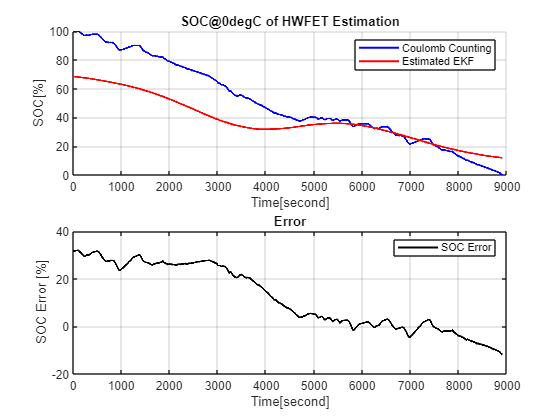

figure
subplot(2,1,1)
hold all
plot (LiIon.RecordingTime,(LiIon.Measured_SOC*100),"blue",'LineWidth',1.5)
plot (LiIon.RecordingTime,(SOC_Estimated*100),"red",'LineWidth',1.5)
legend('Coulomb Counting','Estimated EKF')
ylabel('SOC[%]')
xlabel('Time[second]')
title('SOC@0degC of HWFET Estimation')
grid on
subplot(2,1,2)
plot(LiIon.RecordingTime,(LiIon.Measured_SOC*100) - (SOC_Estimated*100),"black",'LineWidth',1.5);
legend('SOC Error');
ylabel('SOC Error [%]');
xlabel('Time[second]');
title('Error')
grid on

Calculate the root mean square error (RMSE) and the max error (MAX) of both the terminal voltage and SOC.

% Calculate RMSE and MAX of SOC
RMSE_SOC_HWFET_0deg_1    = sqrt((mean(((SOC_Estimated*100) - (LiIon.Measured_SOC*100)).^2))); % (%)
RMSE_SOC_HWFET_0deg_2    = sqrt((mean(((LiIon.Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_HWFET_10deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_HWFET_25deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_HWFET_40deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_HWFET_n10deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_HWFET_n20deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)

%RMSE_SOC_UDDS_0deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_UDDS_10deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_UDDS_25deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_UDDS_40deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_UDDS_n10deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_UDDS_n20deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)

%RMSE_SOC_US06_0deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_US06_10deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_US06_25deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_US06_40deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_US06_n10deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_US06_n20deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)

The DSP_EKF_SOC_Estimation function estimates a battery's terminal voltage (Vt) and state of charge (SOC) using a second order RC equivalent circuit model (ECM) and extended Kalman Filter (EKF). The function takes the following as inputs:

- measured drive cycle current (A)

- measured drive cycle terminal voltage (V)

- battery temperature (C)

Outputs of the function are:

- estimated SOC

- estimated terminal voltage

- SOC Error

- terminal voltage error

- RMSE of terminal voltage and SOC

function [SOC_Estimated, Vt_Estimated, Vt_Error] = DSP_EKF_SOC_Estimation(Current, Vt_Actual, Temperature)
load 'BatteryModel2RCtest.mat'
%load 'BatteryModel.mat'
load 'SOC-OCV.mat'; % Load the SOC-OCV curve

The battery parameters $R0$ to $C2$ were estimated from HPPC or other charaterization tests using the Modeling Batteries Using Simulink and Simscape simulation from the series: [Hybrid Electric Vehicles](https://www.mathworks.com/videos/series/hybrid-electric-vehicles.html) resource available at https://www.mathworks.com/videos/modeling-batteries-using-simulink-and-simscape-1562930245321.html.

$T$ is the measured battery temperature taken at time of the characterization and drive cycle tests.

### Modeled Battery Parameters Initialization

The $scatteredInterpolant$ function performs interpolation on either 2-D or 3-D set of scattered data which is returned as a function. This function is then evaluated each step given that steps temperature and SOC. If there is no temperature data or single temperature data, the $scatteredInterpolant$ can be replaced with $pchip$, an example is given below.

SOC_Init    = 1; % intial SOC
X           = [SOC_Init; 0; 0]; % state space x parameter intializations
DeltaT      = 1; % sample time in seconds
Qn_rated    = 3*3600; % Ah to Amp-seconds

Initialize 2D-Interpolant functions for battery parameters and SOC-OCV curve, this function also allows for extrapolation

F_R0    = scatteredInterpolant(param.T,param.SOC,param.R0);
F_R1    = scatteredInterpolant(param.T,param.SOC,param.R1);
F_R2    = scatteredInterpolant(param.T,param.SOC,param.R2);
F_C1    = scatteredInterpolant(param.T,param.SOC,param.C1);
F_C2    = scatteredInterpolant(param.T,param.SOC,param.C2);
F_OCV   = scatteredInterpolant(param.T,param.SOC,param.OCV);
% OCV can be extrapolated using the same method or through the polyfit function

Fit an odd-order polynomial to the entirety of the SOC-OCV data. This means that only one curve is being used for all the temperatures. For calcuating the C matrix this is required since the $polyder$ function is utilized, however, for calculating the terminal voltage, the $scatteredInterpolant$ function can be used.

SOCOCV  = polyfit(SOC_OCV.SOC,SOC_OCV.OCV,11); % calculate 11th order polynomial for the SOC-OCV curve 
dSOCOCV = polyder(SOCOCV); % derivative of SOC-OCV curve for matrix C

The Kalman Filter has 3 parameters that can vary: $R$, $P$ and $Q$. These will need to be adjusted/tuned for each battery either manually or through an optimization algorithm. $R$ should be set to the square of the error from the equipment used to test the battery cell. Once the value of $Q$ has been tuned, $R$ cannot be updated. 

n_x   = size(X,2);
R_x   = 1e-15;
P_x   = [1e-5 0 0; 0 1e-5 0; 0 0 1e-5];
Q_x   = [1e-15 0 0; 0 1e-10 0; 0 0 1e-10];

Initialize the output vectors and set the length of the for loop based on the size of the current vector.

SOC_Estimated   = [];
Vt_Estimated    = [];
Vt_Error        = [];
ik              = length(Current);
Current         = Current + 5;
Temperature     = Temperature - 7;

## Kalman Filter Algorithm

This is the start of the Extended Kalman Filter algorithm. The loop runs through the length of the data based on the current input.

for k = 1:ik
    T           = Temperature(k);
    U           = Current(k);
    SOC         = X(1);
    V1          = X(2);
    V2          = X(3);

Evaluate the battery parameter scatteredInterpolant 

    R0     = F_R0(SOC,T);
    R1     = F_R1(SOC,T);
    R2     = F_R2(SOC,T);
    C1     = F_C1(SOC,T);
    C2     = F_C2(SOC,T);
    OCV    = F_OCV(SOC,T);
    %OCV    = pchip(param.SOC,param.OCV,SOC); % pchip sample for unknown or single temperature
    
    OCV = polyval(SOCOCV,SOC); % calculate the values of OCV at the given SOC, using the polynomial SOCOCV

The following is used to calculate the A and B matrices below on line 70 and 73.

    Tau_1       = C1 * R1;
    Tau_2       = C2 * R2;

    a1 = exp(-DeltaT/Tau_1);
    a2 = exp(-DeltaT/Tau_2);
    
    b1 = R1 * (1 - exp(-DeltaT/Tau_1));
    b2 = R2 * (1 - exp(-DeltaT/Tau_2));

### Run Update Model

Vt equation is based on:


$$V_t = V_{OC} - V_1 - V_2 - iR_1$$
 

    TerminalVoltage = OCV - V1 - V2 + R0.*U;
    %TerminalVoltage = OCV - R0*U - V1 - V2;

When $U$ (current) is positive and $U$ is negative, the battery is charging. The coulombic efficiency ($\eta$) is set to 1 for lithium-ion batteries but could be less than 1 for lead-acid batteries. Change $eta$ as required.

    if U > 0
        eta = 1; % eta for discharging
    elseif U <= 0 
        eta = 1; % eta for charging
    end

Linearzing the model by linearizing the C matrix. The $polyval$ function returns the value of the polyder function at the selected SOC.


$$JC =  [\frac{\partial V_{OC}}{\partial SOC}   \frac{\partial V}{\partial V_1}  \frac{\partial V}{\partial V_2} ]
	= [\frac{\partial V_{OC}}{\partial SOC}  -1  -1 ]$$


    dOCV = polyval(dSOCOCV, SOC);
    C_x    = [dOCV -1 -1];

Calculate the Vt error.

    Error_x   = Vt_Actual(k) - TerminalVoltage;

Save/update the SOC and voltage estimates in a vector with the Vt error. These are the output vectors of the function.

    Vt_Estimated    = [Vt_Estimated;TerminalVoltage];
    SOC_Estimated   = [SOC_Estimated;X(1)];
    Vt_Error        = [Vt_Error;Error_x];

### Extended Kalman Filter Algorithm

EKF uses a two-step prediction-correction algorithm. Calculate the A and B matrices using the variables from above:

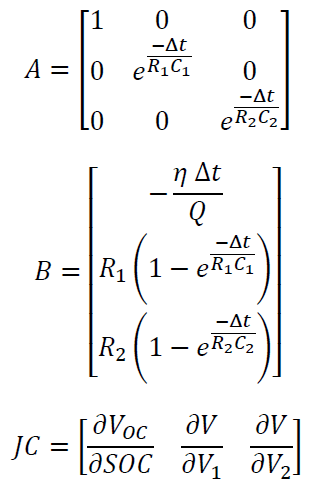

Next, complete the prediction (time update) portion of the KF. 

1. Project the states ahead (a-priori):

2. Project the error covariance ahead:

    A   = [1 0 0; 0 a1 0; 0 0 a2];
    B   = [-(eta * DeltaT/Qn_rated); b1; b2];
    X   = (A.*X) + (B.*U);
    P_x = (A.*P_x.*A') + Q_x;

Next, complete the correction (measurement update) portion of the KF.

1. Compute the Kalman gain:

2. Update estimate with measurement $z_k$ (a-posteriori):

3. Update error covariance:

    KalmanGain_x = (P_x).*(C_x').*(inv((C_x.*P_x.*C_x') + (R_x)));
    X            = X + (KalmanGain_x.*Error_x);
    P_x          = (eye(n_x,n_x) - (KalmanGain_x.*C_x)).*P_x;
end
end

## Copyright Notice

This codes (inlcuding DSP_EKF_SOC_Estimation) is a modified version from from the original works of *State of Charge Estimation Function Based on Kalman Filter *by Fauzia Khanum, Eduardo Louback, Federico Duperly, Colleen Jenkins, Phillip Kollmeyer, Ali Emadi under BSD 3 Clause license. All right reserved.

## Reference

[1] Khanum, F. (2021, June 29). *State of charge estimation function based on Kalman filter*. File Exchange - MATLAB Central. [https://www.mathworks.com/matlabcentral/fileexchange/90381-state-of-charge-estimation-function-based-on-kalman-filter](https://www.mathworks.com/matlabcentral/fileexchange/90381-state-of-charge-estimation-function-based-on-kalman-filter) 

[2] Kollmeyer, Phillip. (2020, December 24). *Samsung INR21700 30T 3AH Li-Ion Battery Data*. Mendeley Data. [https://doi.org/10.17632/9xyvy2njj3.1](https://doi.org/10.17632/9xyvy2njj3.1) 

[3] *Mathworks smoothdata*. Smooth noisy data - MATLAB. (2023). [https://www.mathworks.com/help/matlab/ref/smoothdata.html](https://www.mathworks.com/help/matlab/ref/smoothdata.html) 